Declaración de Variables Simbólicas

clear;clc;
syms x xi(t) L a1(t) b1(t) a2(t) b2(t) TH TC
syms a_1 a_2

Variables Termodinámicas

syms T_f L_f rho k1 k2 C1 C2

# Método de Goodman

Proponemos Distribuciones Cuadráticas de Temperatura en cada fase. Distribuciones que satisfacen las condiciones de frontera.


$$T_{\ell}(x,t)=a_{\ell}\big(x-\xi(t)\big)+b_{\ell}\big(x-\xi(t)\big)^2+T_f$$



$$T_{s}(x,t)=a_{s}\big(x-\xi(t)\big)+b_{s}\big(x-\xi(t)\big)^2+T_f$$


# Condiciones Isotérmicas


$$T_{\ell}(0,t)=T_{\mathbb{H}},\,\,\, {\rm{donde}}\,\,\,T_{\mathbb{H}}>T_f$$



$$T_{s}(L,t)=T_{\mathbb{C}},\,\,\, {\rm{donde}}\,\,\,T_{\mathbb{C}}<T_f$$


*L* representa el espesor de la placa. Imponemos C.F. y obtenemos los las funciones $a_{\ell}(t)\, {\rm{y}} \, a_{s}(t)$

T1(x,t)=a1(t)*(x-xi(t))+b1(t)*(x-xi(t))^2+T_f

$$T1(x, t) = T_{f}+a_{1}\left(t\right)\,\left(x-\xi \left(t\right)\right)+b_{1}\left(t\right)\,{\left(x-\xi \left(t\right)\right)}^{2}$$

T2(x,t)=a2(t)*(x-xi(t))+b2(t)*(x-xi(t))^2+T_f

$$T2(x, t) = T_{f}+a_{2}\left(t\right)\,\left(x-\xi \left(t\right)\right)+b_{2}\left(t\right)\,{\left(x-\xi \left(t\right)\right)}^{2}$$

eq1=T1(0,t)==TH

$$eq1 = b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-a_{1}\left(t\right)\,\xi \left(t\right)+T_{f}=\mathrm{TH}$$

eq2=T2(L,t)==TC

$$eq2 = T_{f}+a_{2}\left(t\right)\,\left(L-\xi \left(t\right)\right)+b_{2}\left(t\right)\,{\left(L-\xi \left(t\right)\right)}^{2}=\mathrm{TC}$$

Ecuación de Balance de Energía en la Interfaz Líquido-Sólido. Ecuación de movimiento de la interfaz


$$L_f\rho\frac{d\xi(t)}{dt}=-k_{\ell}\frac{\partial\,T_{\ell}(x,t)}{\partial\,x}\bigg\vert_{x=\xi(t)}+-k_{s}\frac{\partial\,T_{s}(x,t)}{\partial\,x}\bigg\vert_{x=\xi(t)}$$


deq1=L_f*rho*diff(xi(t),t)==-k1*subs(diff(T1(x,t),x),x,xi(t))+k2*subs(diff(T2(x,t),x),x,xi(t))

$$deq1 = L_{f}\,\rho \,\frac{\partial }{\partial t}\xi \left(t\right)=k_{2}\,a_{2}\left(t\right)-k_{1}\,a_{1}\left(t\right)$$

Balance Local de Energía. Ecuación de Calor

Se promedia cada ecuación de calor en el dominio del líquido y en el dominio del sólido. Método de la Integral de Balance de Calor

$\rho\,C_{\ell}\frac{d}{dt}\int^{\xi(t)}_{0}T_{\ell}(x,t)dx-T_{\ell}(\xi(t),t)\frac{d\xi(t)}{dt}-k_{\ell}\int^{\xi(t)}_{0}\frac{\partial^2T_{\ell}(x,t)}{\partial\,x^2}=0$ y


$$\rho\,C_{s}\frac{d}{dt}\int^{L}_{\xi(t)}T_{\ell}(x,t)dx+T_{s}(\xi(t),t)\frac{d\xi(t)}{dt}-k_{s}\int^{L}_{\xi(t)}\frac{\partial^2T_{s}(x,t)}{\partial\,x^2}=0$$


Se obtienen dos ecuaciones diferenciales ordinarias en el tiempo. Una para cada fase:

deq2=rho*C1*simplify(diff(int(T1(x,t),x,0,xi(t)),t)-T1(xi(t),t)*diff(xi(t),t))-k1*int(diff(diff(T1(x,t),x),x),x,0,xi(t))==0

$$deq2 = -C_{1}\,\rho \,\left(\frac{{\xi \left(t\right)}^{2}\,\frac{\partial }{\partial t}a_{1}\left(t\right)}{2}-\frac{{\xi \left(t\right)}^{3}\,\frac{\partial }{\partial t}b_{1}\left(t\right)}{3}-b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}\,\frac{\partial }{\partial t}\xi \left(t\right)+a_{1}\left(t\right)\,\xi \left(t\right)\,\frac{\partial }{\partial t}\xi \left(t\right)\right)-2\,k_{1}\,b_{1}\left(t\right)\,\xi \left(t\right)=0$$

Para el líquido, y

deq3=rho*C2*simplify(diff(int(T2(x,t),x,xi(t),L),t)+T2(xi(t),t)*diff(xi(t),t))-k2*int(diff(diff(T2(x,t),x),x),x,xi(t),L)==0

$$deq3 = \frac{C_{2}\,\rho \,\left(L-\xi \left(t\right)\right)\,\left(3\,L\,\frac{\partial }{\partial t}a_{2}\left(t\right)+2\,{\xi \left(t\right)}^{2}\,\frac{\partial }{\partial t}b_{2}\left(t\right)+2\,L^{2}\,\frac{\partial }{\partial t}b_{2}\left(t\right)-6\,a_{2}\left(t\right)\,\frac{\partial }{\partial t}\xi \left(t\right)-3\,\xi \left(t\right)\,\frac{\partial }{\partial t}a_{2}\left(t\right)-6\,L\,b_{2}\left(t\right)\,\frac{\partial }{\partial t}\xi \left(t\right)-4\,L\,\xi \left(t\right)\,\frac{\partial }{\partial t}b_{2}\left(t\right)+6\,b_{2}\left(t\right)\,\xi \left(t\right)\,\frac{\partial }{\partial t}\xi \left(t\right)\right)}{6}-2\,k_{2}\,b_{2}\left(t\right)\,\left(L-\xi \left(t\right)\right)=0$$

Usamos las C.F. Isotérmicas despejando a1 y a2 de la eq1 y la eq2

a_1=solve(subs(eq1,a1(t),a_1),a_1)

$$a\_1 = \frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\mathrm{TH}+T_{f}}{\xi \left(t\right)}$$

a_2=solve(subs(eq2,a2(t),a_2),a_2)

$$a\_2 = -\frac{T_{f}-\mathrm{TC}+b_{2}\left(t\right)\,{\left(L-\xi \left(t\right)\right)}^{2}}{L-\xi \left(t\right)}$$

Sustitución de las variables a1 y a2 en las ecuaciones diferenciales

deq11=subs(deq1,{a1(t),a2(t)},{a_1,a_2});
deq111=collect(subs(deq11,{L_f rho k1 k2 TC TH T_f L},...
    {396000 2545 225 215 873.25 1173 933.52 1}),...
    diff(xi(t),t));
deq1111 = collect(lhs(deq111)-rhs(deq111),diff(xi(t),t))==0

$$deq1111 = 1007820000\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}-\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1}=0$$

NOPER_deq1111 = nop(op(1,deq1111));

$$s = \left(\begin{array}{cc} 1007820000\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}-\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1} & 0 \end{array}\right)$$

$$s = \left(\begin{array}{cc} 1007820000\,\frac{\partial }{\partial t}\xi \left(t\right) & \frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}-\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1} \end{array}\right)$$

A(1,:) = [op(1,op(1,deq1111))/diff(xi(t),t) 0 0];

$$s = \left(\begin{array}{cc} 1007820000\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}-\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1} & 0 \end{array}\right)$$

$$s = \left(\begin{array}{cc} 1007820000\,\frac{\partial }{\partial t}\xi \left(t\right) & \frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}-\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1} \end{array}\right)$$

B(1,1) = -op(NOPER_deq1111,op(1,deq1111))

$$s = \left(\begin{array}{cc} 1007820000\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}-\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1} & 0 \end{array}\right)$$

$$s = \left(\begin{array}{cc} 1007820000\,\frac{\partial }{\partial t}\xi \left(t\right) & \frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}-\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1} \end{array}\right)$$

$$B = -\frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}+\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1}$$

deq22=subs(deq2,{a1(t)},{a_1});
deq222=collect(subs(deq22,{rho C1 k1 TH T_f},...
    {2545 1130 225 1173 933.52}),...
    [diff(xi(t),t) diff(b1(t),t)]);
deq2222=collect(lhs(deq222)-rhs(deq222),...
        [diff(xi(t),t) diff(b1(t),t)] )==0

$$deq2222 = \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right)+\left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right)-450\,b_{1}\left(t\right)\,\xi \left(t\right)=0$$

NOPER_deq2222 = nop(op(1,deq2222));

$$s = \left(\begin{array}{cc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right)+\left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right)-450\,b_{1}\left(t\right)\,\xi \left(t\right) & 0 \end{array}\right)$$

$$s = \left(\begin{array}{ccc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right) & \left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right) & -450\,b_{1}\left(t\right)\,\xi \left(t\right) \end{array}\right)$$

A(2,:) = [op(1,op(1,deq2222))/diff(xi(t),t) op(2,op(1,deq2222))/diff(b1(t),t) 0];

$$s = \left(\begin{array}{cc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right)+\left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right)-450\,b_{1}\left(t\right)\,\xi \left(t\right) & 0 \end{array}\right)$$

$$s = \left(\begin{array}{ccc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right) & \left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right) & -450\,b_{1}\left(t\right)\,\xi \left(t\right) \end{array}\right)$$

$$s = \left(\begin{array}{cc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right)+\left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right)-450\,b_{1}\left(t\right)\,\xi \left(t\right) & 0 \end{array}\right)$$

$$s = \left(\begin{array}{ccc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right) & \left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right) & -450\,b_{1}\left(t\right)\,\xi \left(t\right) \end{array}\right)$$

B(2,1) = -op(NOPER_deq2222,op(1,deq2222))  

$$s = \left(\begin{array}{cc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right)+\left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right)-450\,b_{1}\left(t\right)\,\xi \left(t\right) & 0 \end{array}\right)$$

$$s = \left(\begin{array}{ccc} \left(688708558-1437925\,{\xi \left(t\right)}^{2}\,\left(2\,b_{1}\left(t\right)-\frac{b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}}{{\xi \left(t\right)}^{2}}\right)\right)\,\frac{\partial }{\partial t}\xi \left(t\right) & \left(-\frac{1437925\,{\xi \left(t\right)}^{3}}{3}\right)\,\frac{\partial }{\partial t}b_{1}\left(t\right) & -450\,b_{1}\left(t\right)\,\xi \left(t\right) \end{array}\right)$$

$$B = \left(\begin{array}{c} -\frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}+\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1}\\ 450\,b_{1}\left(t\right)\,\xi \left(t\right) \end{array}\right)$$

deq33=subs(deq3,{a2(t)},{a_2});
deq333=collect(subs(deq33,{rho C2 k2 TC T_f L},...
    {2545 1016 215 873.25 933.52 1}),...
    [diff(xi(t),t) diff(b1(t),t)]);
deq3333=collect(lhs(deq333)-rhs(deq333),...
        [diff(xi(t),t) diff(b2(t),t)] )==0

$$deq3333 = \begin{array}{l} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right)+430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right)=0\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

NOPER_deq3333 = nop(op(1,deq3333));

$$s = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right)+430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

$$s = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right) & \frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right) & 430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

A(3,:) = [op(1,op(1,deq3333))/diff(xi(t),t) 0 op(2,op(1,deq3333))/diff(b2(t),t)];

$$s = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right)+430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

$$s = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right) & \frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right) & 430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

$$s = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right)+430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

$$s = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right) & \frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right) & 430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

B(3,1) = -op(NOPER_deq3333,op(1,deq3333))

$$s = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right)+\frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right)+430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

$$s = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(\xi \left(t\right)-1\right)\,\left(3\,\xi \left(t\right)\,\left(2\,b_{2}\left(t\right)-\frac{\sigma_{1}}{\sigma_{2}}\right)-6\,b_{2}\left(t\right)\,\xi \left(t\right)+\frac{6\,\sigma_{1}}{\xi \left(t\right)-1}+\frac{3\,\sigma_{1}}{\sigma_{2}}\right)\,1292860}{3}\,\frac{\partial }{\partial t}\xi \left(t\right) & \frac{1292860\,\left(\xi \left(t\right)-1\right)\,\left(\xi \left(t\right)-2\,{\xi \left(t\right)}^{2}+3\,\xi \left(t\right)\,\left(\xi \left(t\right)-1\right)+1\right)}{3}\,\frac{\partial }{\partial t}b_{2}\left(t\right) & 430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{2}\left(t\right)\,\sigma_{2}+\frac{6027}{100}\\ \sigma_{2}={\left(\xi \left(t\right)-1\right)}^{2} \end{array}$$

$$B = \left(\begin{array}{c} -\frac{225\,\left(b_{1}\left(t\right)\,{\xi \left(t\right)}^{2}-\frac{5987}{25}\right)}{\xi \left(t\right)}+\frac{215\,\left(b_{2}\left(t\right)\,{\left(\xi \left(t\right)-1\right)}^{2}+\frac{6027}{100}\right)}{\xi \left(t\right)-1}\\ 450\,b_{1}\left(t\right)\,\xi \left(t\right)\\ -430\,b_{2}\left(t\right)\,\left(\xi \left(t\right)-1\right) \end{array}\right)$$

Como se puede ver, las ecuaciones diferenciales están escritas en forma matricial


$$A\;u=B$$


donde


$$u=\left\lbrack \begin{array}{c}
\frac{\partial {\;\xi }_{\varepsilon } }{\partial \;t}\\
\frac{\partial {\;\xi }_{\gamma } }{\partial \;t}\\
\frac{\partial {\;\xi }_{\alpha } }{\partial \;t}\\
\frac{\partial {\;b}_1 }{\partial \;t}\\
\frac{\partial {\;b}_2 }{\partial \;t}\\
\frac{\partial {\;b}_3 }{\partial \;t}
\end{array}\right\rbrack$$


syms y1 y2 y3;
AA = simplify(subs(A,{xi(t), b1(t), b2(t)},{y1, y2, y3}))

$$AA = \left(\begin{array}{ccc} 1007820000 & 0 & 0\\ 344354279-1437925\,{y_{1}}^{2}\,y_{2} & -\frac{1437925\,{y_{1}}^{3}}{3} & 0\\ 1292860\,y_{3}\,{y_{1}}^{2}-2585720\,y_{3}\,y_{1}+1292860\,y_{3}+\frac{389603361}{5} & 0 & \frac{1292860\,{\left(y_{1}-1\right)}^{3}}{3} \end{array}\right)$$

BB = simplify(subs(B,{xi(t), b1(t), b2(t)},{y1, y2, y3}))

$$BB = \left(\begin{array}{c} \frac{215\,\left(y_{3}\,{\left(y_{1}-1\right)}^{2}+\frac{6027}{100}\right)}{y_{1}-1}-\frac{225\,\left({y_{1}}^{2}\,y_{2}-\frac{5987}{25}\right)}{y_{1}}\\ 450\,y_{1}\,y_{2}\\ -430\,y_{3}\,\left(y_{1}-1\right) \end{array}\right)$$

**Condiciones Iniciales. Perfiles de temperatura en t=0 segundos**

L_f = 396000; T_f=933.52; rho=2545; C1=1130; C2=1016; k1=225; k2=215;
TH = 1173; TC = 873.25; xi_inic=0.2; L=1;
syms aa1 aa2 bb1 bb2;

Distribución Inicial de Temperatura en el Líquido

Tliq = T_f+aa1*(x-xi_inic)+bb1*(x-xi_inic)^2

$$Tliq = {\mathrm{aa}}_{1}\,\left(x-\frac{1}{5}\right)+{\mathrm{bb}}_{1}\,{\left(x-\frac{1}{5}\right)}^{2}+\frac{23338}{25}$$

Distribución Inicial de Temperatura en el Sólido

Tsol = T_f+aa2*(x-xi_inic)+bb2*(x-xi_inic)^2

$$Tsol = {\mathrm{aa}}_{2}\,\left(x-\frac{1}{5}\right)+{\mathrm{bb}}_{2}\,{\left(x-\frac{1}{5}\right)}^{2}+\frac{23338}{25}$$

Condición de Frontera Isotérmica Para el Líquido

eq3 = subs(Tliq,x,0)==TH

$$eq3 = \frac{{\mathrm{bb}}_{1}}{25}-\frac{{\mathrm{aa}}_{1}}{5}+\frac{23338}{25}=1173$$

Condición de Frontera Inicial de tipo Adiabática Para el Líquido (Esta C.F. sólo la usamos al inicio para obtener el valor de b1 en t=0 segundos)

eq4 = subs(diff(Tliq,x),x,0)==0

$$eq4 = {\mathrm{aa}}_{1}-\frac{2\,{\mathrm{bb}}_{1}}{5}=0$$

Condición de Frontera Isotérmica para el Sólido

eq5 = subs(Tsol,x,L)==TC

$$eq5 = \frac{4\,{\mathrm{aa}}_{2}}{5}+\frac{16\,{\mathrm{bb}}_{2}}{25}+\frac{23338}{25}=\frac{3493}{4}$$

Condición de Frontera Inicial de tipo Adiabática Para el Sólido (Esta C.F. sólo la usamos al inicio para obtener el valor de b2 en t=0 segundos)

eq6 = subs(diff(Tsol,x),x,L)==0

$$eq6 = {\mathrm{aa}}_{2}+\frac{8\,{\mathrm{bb}}_{2}}{5}=0$$

Solición Algebráica para las Eqns. 3 y 4 (C.F. en el Líquido para obtener los valores iniciales de a1 y b1)

[aa1,bb1] = solve([eq3,eq4],[aa1,bb1])

$$aa1 = -\frac{11974}{5}$$

$$bb1 = -5987$$

aa1=double(aa1)

aa1 = -2.3948e+03

bb1=double(bb1)

bb1 = -5987

[aa2,bb2] = solve([eq5,eq6],[aa2,bb2])

$$aa2 = -\frac{6027}{40}$$

$$bb2 = \frac{6027}{64}$$

aa2=double(aa2)

aa2 = -150.6750

bb2=double(bb2)

bb2 = 94.1719

Así queda el perfil de temperatura inicial en el Líquido

eval(Tliq)

$$ans = \frac{35312}{25}-5987\,{\left(x-\frac{1}{5}\right)}^{2}-\frac{11974\,x}{5}$$

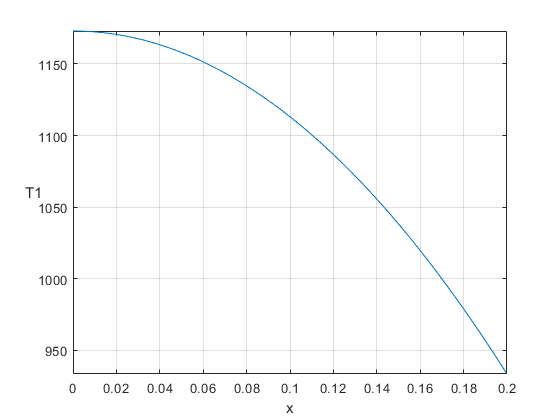

fplot(eval(Tliq),[0 xi_inic]);grid on;xlabel('x');ylabel('T1','rotation',0)

Así queda el perfil de temperatura inicial en el Sólido

eval(Tsol)

$$ans = \frac{6027\,{\left(x-\frac{1}{5}\right)}^{2}}{64}-\frac{6027\,x}{40}+\frac{192731}{200}$$

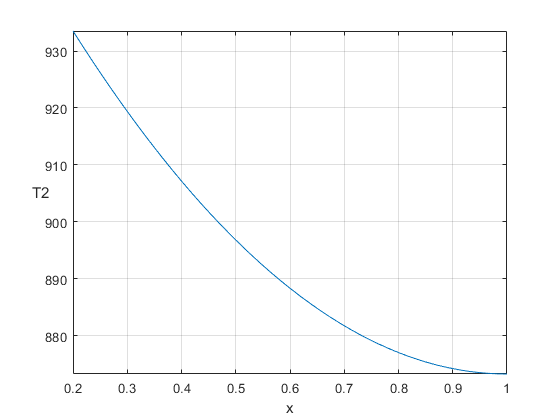

fplot(eval(Tsol),[xi_inic L]);grid on;xlabel('x');ylabel('T2','rotation',0)

Distribución de Temperatura Inicial en toda la muestra

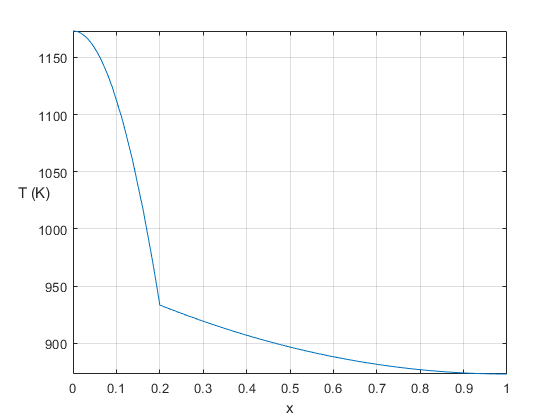

TempDist = piecewise(x<xi_inic,eval(Tliq), ...
        x>=xi_inic & x<= L,eval(Tsol));
fplot(TempDist,[0 L]);grid on;xlabel('x');ylabel('T (K)','rotation',0);

Solución del Modelo

Condiciones Iniciales

y0=[xi_inic;bb1;bb2];

Sistema de Ecuaciones

Fun = @(t,y) double(subs(AA\BB,{y1, y2, y3},{y(1), y(2), y(3)}));

Intervalo de tiempo durante el cual se va a resolver este sistema

tspan = [0,20000];

Solución usando Runge Kutta

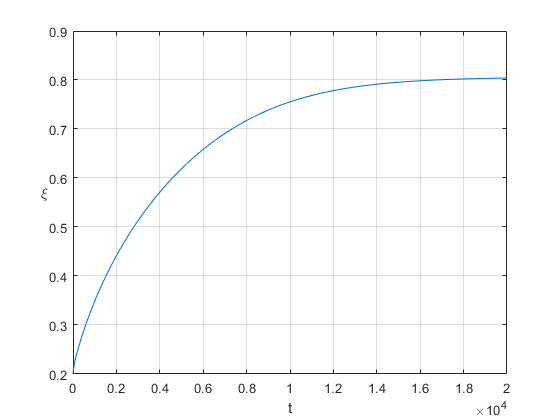

[t,y]=ode45(Fun,tspan,y0);
plot(t,y(:,1));grid on;xlabel('t');ylabel('\xi','rotation',0);

Límite en el Estado Estacionario. El neto de calor en la interfaz es cero, por lo tanto


$$\xi_{\rm{lim}}=\frac{k_{\ell}\big(T_{\mathbb{H}}-T_f\big)}{k_{\ell}\big(T_{\mathbb{H}}-T_f\big)+k_{s}\big(T_f-T_{\mathbb{C}}\big)}L$$


En este ejemplo donde k1=225, k2=215, TH=1173 y TC=873.25 para una muestra de 1.0 m de Espesor

%%
xilim=double(k1)*(double(TH)-double(T_f))/(double(k1)*(double(TH)-double(T_f))+double(k2)*(double(T_f)-double(TC)))

xilim = 0.8061

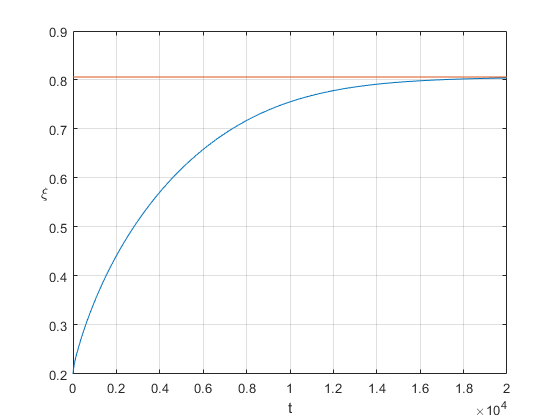

tiempo=zeros(477,1);
xistat=zeros(477,1);
T=0.0d0;
DT=20000.0d0/477.0d0;
for i=1:477
    tiempo(i)=T+DT;
    xistat(i)=xilim;
end
plot(t,[y(:,1),xistat(:,1)]);grid on;xlabel('t');ylabel('\xi','rotation',0);

function exp2 = op(n,exp1)
    s=children(exp1);
    s = [s{:}]
    exp2 = s(n);
end

function n = nop(exp1)
    s=children(exp1);
    s = [s{:}]
    n = size(s,2);
end